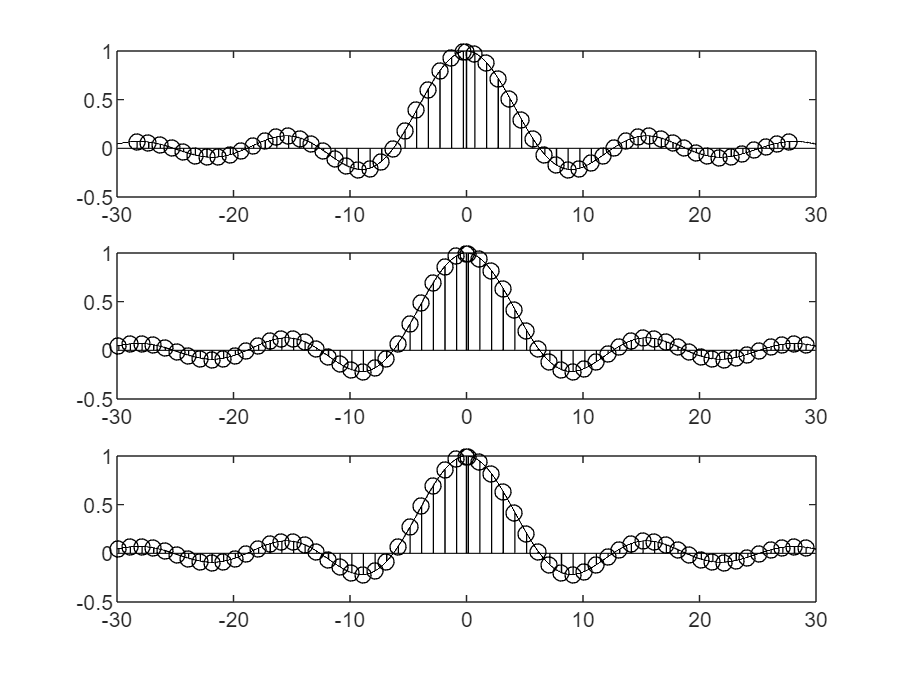

clc,clear,close all;
T1=0.5;
w=-30:0.01:30;
y=2*sin(w.*T1)./w;

N1=4;
w0_1=2*pi/N1/T1;
k1=fix(30/w0_1);
w1=-k1*w0_1:k1*w0_1;
y1=2*sin(w1.*T1)./w1;
figure;
subplot(3,1,1);
plot(w,y,'-k');
hold on;
plot(0,1,'-k');
hold on;
stem(w1,y1,'ko');
hold on;
stem(0,1,'ko');
hold off;

N2=8;
w0_2=2*pi/N2/T1;
k2=fix(30/w0_2);
w2=-k2*w0_2:k2*w0_2;
y2=2*sin(w2.*T1)./w2;
subplot(3,1,2);
plot(w,y,'-k');
hold on;
plot(0,1,'-k');
hold on;
stem(w2,y2,'ko');
hold on;
stem(0,1,'ko');
hold off;

N3=16;
w0_3=2*pi/N3/T1;
k3=fix(30/w0_3);
w3=-k3*w0_3:k3*w0_3;
y3=2*sin(w3.*T1)./w3;
subplot(3,1,3);
plot(w,y,'-k');
hold on;
plot(0,1,'-k');
hold on;
stem(w3,y3,'ko');
hold on;
stem(0,1,'ko');
hold off;

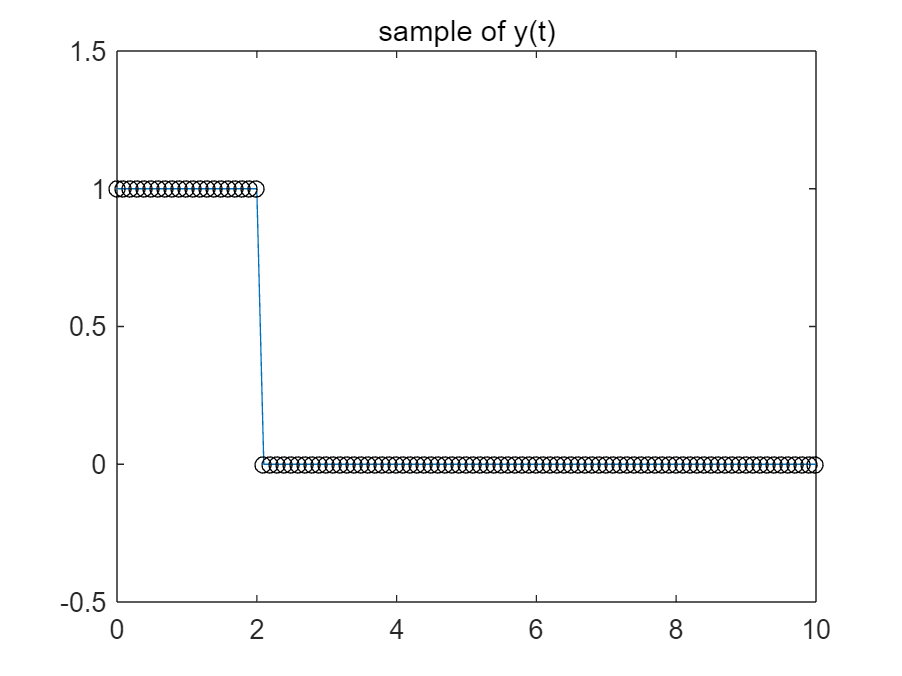

clc,clear,close all;
tau=0.1;
N=101; % let N be odd to get symmetrical result, N*tau=T>2
t=0:tau:(N-1)*tau;
y=[ones(1,fix(2/tau)+1),zeros(1,N-1-fix(2/tau))]; %sample y(t)
plot(t,y),hold on,scatter(t,y,'ko'),ylim([-0.5 1.5]),title('sample of y(t)');
hold off;

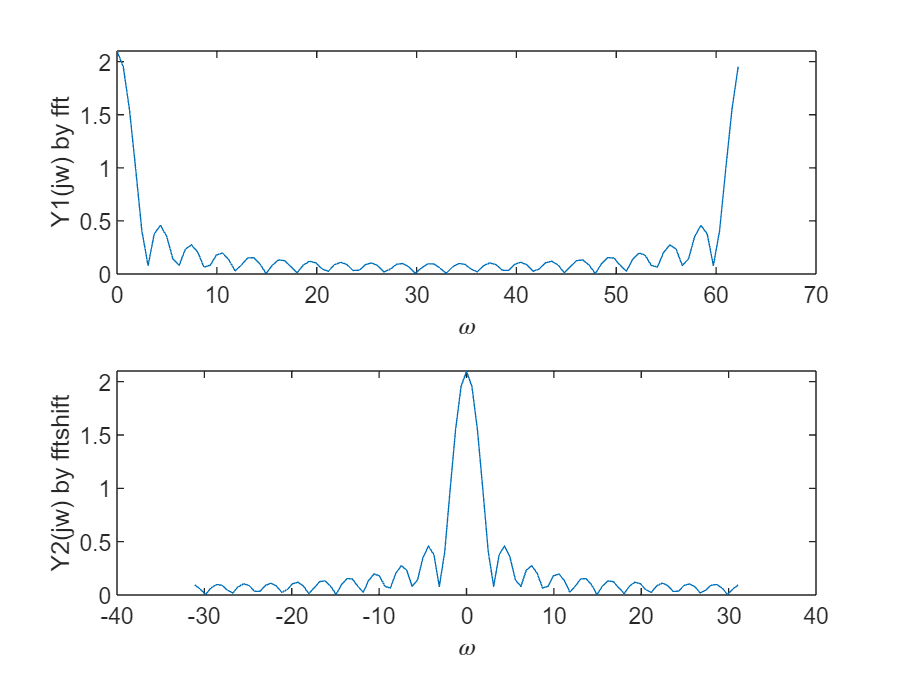

%caculate Y1(jw) by fft, Y2(jw) by fftshift
Y1=tau*fft(y);
Y2=fftshift(tau*fft(y));
w1=0:2*pi/N/tau:2*pi*(N-1)/N/tau;
w2=(1-N)*pi/N/tau+(0:N-1)*2*pi/N/tau;
figure;
subplot(2,1,1),plot(w1,abs(Y1)),xlabel('\omega'),ylabel('Y1(jw) by fft');
subplot(2,1,2),plot(w2,abs(Y2));xlabel('\omega'),ylabel('Y2(jw) by fftshift');